# Matrix Operations

Wherever you find digital data, you will find matrices.

        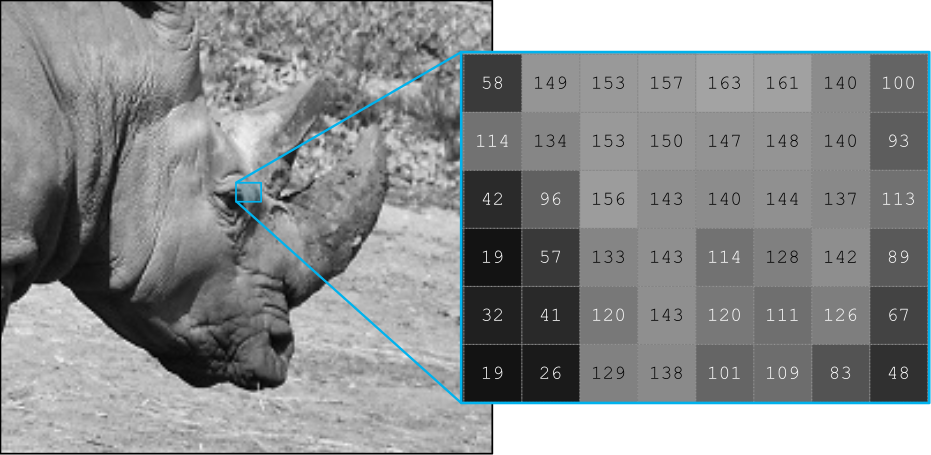

        *Grayscale images are large matrices of pixel intensities*

It's easy to see how you can apply a mathematical operation to a single element of a matrix:

    $58 \times 3 = 174$.

However, it's not as clear how these operators apply to full matrices.

    
$$\left( \matrix{ 58 & 149 \cr 114 & 134 } \right) \times \left( \matrix{ 1 & 0 \cr -2 & 3 } \right) = ?$$


In this live script, you'll learn the definitions of basic matrix operations and practice computing them by hand and in MATLAB.

 This live script is intended to be used with the code hidden. Select the `VIEW` tab and switch to `Hide Code`.

## Matrix operations

- In this live script, the same numeric values are used in $\mathbf{A}$, $\mathbf{B}$, $\mathbf{v}$, and $c$.

- You can run this section to generate new random versions of $\mathbf{A}$, $\mathbf{B}$, $\mathbf{v}$, and $c$.

- Running this section also clears the workspace.

 
close all
clear all
[Ai,Bi,ci,vi] = defineMatrices;
disp("Matrices have been (re)defined.")

Note that the matrices defined here are $10 \times 10$, but you can adjust the sizes in the following sections to select a suitably sized submatrix.

### Definition

A matrix is a rectangular set of elements. The $m \times n$ matrix shown here has $m$ rows and $n$ columns.

    
$$\mathbf{A} = \left(\begin{array}{ccc}
a_{11}  &  a_{12} & \ldots  & a_{1n} \\
a_{21} & a_{22}   & \ldots  & a_{2n} \\
\vdots &  \vdots   & \ddots  & \vdots \\
a_{m1}  & a_{m2} & \ldots  & a_{mn} 
\end{array}\right)$$


Each element is denoted $a_{i,j}$, where $i$ refers to the row and $j$ to the column.

  **Try**. 

- Adjust the number of rows ($m$) and columns ($n$) to view $\mathbf{A}$ with different sizes.

- View a concrete example of a numeric matrix by selecting the checkbox.

m = 5;
n = 5; 
numeric = false;
 
validateMatrices % This helper ensures that the matrices are defined
if(numeric) 
    A = sym(Ai(1:m,1:n))
else
    A = sym('a',[m,n])
end

### Addition and subtraction

To add two $n \times m$ matrices, add their corresponding elements.

    
$$\mathbf{A} + \mathbf{B} = \left(\begin{array}{ccc}
a_{11}  &  a_{12} & \ldots  & a_{1n} \\
a_{21} & a_{22}   & \ldots  & a_{2n} \\
\vdots &  \vdots   & \ddots  & \vdots \\
a_{m1}  & a_{m2} & \ldots  & a_{mn} 
\end{array}\right) 
+ 
\left(\begin{array}{ccc}
b_{11}  &  b_{12} & \ldots  & b_{1n} \\
b_{21} & b_{22}   & \ldots  & b_{2n} \\
\vdots &  \vdots   & \ddots  & \vdots \\
b_{m1}  & b_{m2} & \ldots  & b_{mn} 
\end{array}\right)$$


               
$$= \left(\begin{array}{ccc}
a_{11} + b_{11}  &  a_{12} + b_{12} & \ldots  & a_{1n} +b_{1n}  \\
a_{21} + b_{21} & a_{22} + b_{22} & \ldots  & a_{2n} + b_{2n} \\
\vdots &  \vdots   & \ddots  & \vdots \\
a_{m1}  + b_{m1} & a_{m2} + b_{m2} & \ldots  & a_{mn}  + b_{mn} 
\end{array}\right)$$


To subtract matrices, subtract the corresponding elements. To add or subtract two matrices, they must be the same size. 

 **Exercise**. Subtract matrices $\mathbf{A}$ and $\mathbf{B}$. You can adjust their sizes. 

m = 3;
n = 3; 
 
validateMatrices % This helper ensures that the matrices are defined
A = sym(Ai(1:m,1:n));
B = sym(Bi(1:m,1:n));
displayFormula(["'A = '", "A", "'          B = '", "B"])
showSolution = false;
if(showSolution)
    AminusB = A-B;
    displayFormula(["'A - B = '", "AminusB"])
end

 **Reflect.  **Consider the matrix $\mathbf{D}$ shown below. Can you compute $\mathbf{A} + \mathbf{D}$?

BD = sym(Bi(1:m,1:(n+1)));
displayFormula(["'D = '", "BD"])

### Multiplication by a scalar

When multiplying a matrix $A$ by a scalar $c$, multiply each element by the scalar.

    
$$c\mathbf{A} = \left(\begin{array}{ccc}
ca_{11}  &  ca_{12} & \ldots  & ca_{1n} \\
ca_{21} & ca_{22}   & \ldots  & ca_{2n} \\
\vdots &  \vdots   & \ddots  & \vdots \\
ca_{m1}  & ca_{m2} & \ldots  & ca_{mn} 
\end{array}\right)$$


  **Exercise**. Multiply the matrix $\mathbf{A}$ by the scalar $c$. You can adjust the size of $\mathbf{A}$.

m = 3;
n = 3; 
 
validateMatrices % This helper ensures that the matrices are defined
A = sym(Ai(1:m,1:n));
displayFormula(["'A = '", "A"])
c = sym(ci);
displayFormula(["'c = '", "c"])
showSolution2 = false;
if(showSolution2)
    cA = ci*A;
    displayFormula(["'cA = '", "cA"])
end

### Multiplication by a column vector

The product of a $m \times n$ matrix $\mathbf{A}$ and an $n$ element column vector $\mathbf{v}$ yields a column vector. The entries of the product $\mathbf{Av}$ are the dot product of the rows of $\mathbf{A}$ with the vector $\mathbf{v}$:

    
$$\mathbf{Av} = \left(\begin{array}{ccc}
a_{11}  &  a_{12} & \ldots  & a_{1n} \\
a_{21} & a_{22}   & \ldots  & a_{2n} \\
\vdots &  \vdots   & \ddots  & \vdots \\
a_{m1}  & a_{m2} & \ldots  & a_{mn} 
\end{array}\right)
\left(\begin{array}{ccc}
v_{1} \\
v_{2} \\
\vdots \\
v_{n} 
\end{array}\right)$$


          
$$= \left(\begin{array}{ccc}
a_{11} v_1  +  a_{12} v_2  + \ldots  + a_{1n}v_n \\
a_{21} v_1  +  a_{22} v_2  + \ldots  + a_{2n}v_n\\
\vdots \\
a_{m1} v_1  +  a_{m2} v_2  + \ldots  + a_{mn}v_n\\
\end{array}\right)$$


To take the dot product of the rows of $\mathbf{A}$ and the vector $\mathbf{v}$, the number of columns in $\mathbf{A}$ must match the number of elements in $\mathbf{v}$. This implies $\mathbf{v}$ must have $n$ entries.

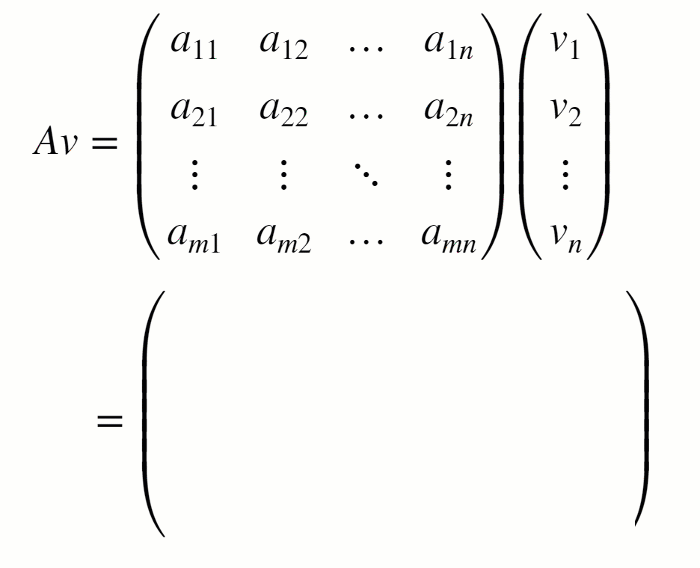

*Animation of matrix-vector multiplication. Each entry in the result is created by taking the dot product of the matrix row and the vector.*

 **Exercise**. Compute the matrix-vector product $\mathbf{A} \mathbf{v}$. You can adjust the sizes.

m = 3;
n = 3; 
 
validateMatrices % This helper ensures that the matrices are defined
A = sym(Ai(1:m,1:n));
displayFormula(["'A = '", "A"])
v = sym(vi(1:n));
displayFormula(["'v = '", "v"])
validateMatrices % This helper ensures that the matrices are defined
showSolution3 = false;
if(showSolution3)
    Av = A*v;
    displayFormula(["'Av = '", "Av"])
end

 **Reflect.  **Consider the vector $\mathbf{u}$ shown below. Can you compute $\mathbf{A}\mathbf{u}$?

u = sym(vi(1:(n+2)));
displayFormula(["'u = '", "u"])

### Multiplication by another matrix

The product of a $m \times n$ matrix $\mathbf{A}$ and an $n \times p$ matrix $\mathbf{B}
$ is a $m \times p$ matrix $\mathbf{C}
$, defined below.  Note that the "inner" dimensions of $\mathbf{A}$ and $\mathbf{B}
$ must match for their product to be defined.

    
$$\mathbf{AB} = \left(\begin{array}{ccc}
a_{11}  &  a_{12} & \ldots  & a_{1n} \\
a_{21} & a_{22}   & \ldots  & a_{2n} \\
\vdots &  \vdots   & \ddots  & \vdots \\
a_{m1}  & a_{m2} & \ldots  & a_{mn} 
\end{array}\right)

\left(\begin{array}{ccc}
b_{11}  & b_{12} & \ldots  & b_{1p} \\
b_{21} & b_{22}   & \ldots  & b_{2p} \\
\vdots &  \vdots   & \ddots  & \vdots \\
b_{n1}  & b_{n2} & \ldots  & b_{np} 
\end{array}\right)$$


          
$$=
\left(\begin{array}{ccc}
c_{11}  & c_{12} & \ldots  & c_{1p} \\
c_{21} & c_{22}   & \ldots  & c_{2p} \\
\vdots &  \vdots   & \ddots  & \vdots \\
c_{m1}  & c_{m2} & \ldots  & c_{mp} 
\end{array}\right)$$


where

    
$$c_{ij} = \sum_{k} a_{ik}b_{kj}$$


If the matrices' inner dimensions do not match, the rows of $A$ will not have the same length as the columns of $B$, and this sum will not be defined.

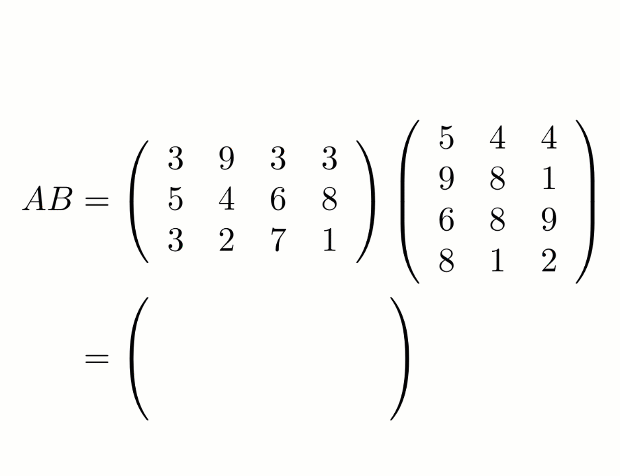

*Example of matrix multiplication. Each element in the product is created by taking the dot product of a row of A with a column of B.*

 **Exercise**. Multiply the matrices $A$ and $B$. You can adjust the sizes.

m = 3;
n = 3; 
p = 3;
 
validateMatrices % This helper ensures that the matrices are defined
A = sym(Ai(1:m,1:n));
displayFormula(["'A = '", "A"])
B = sym(Bi(1:n,1:p));
displayFormula(["'B = '", "B"])
showSolution3 = false;
if(showSolution3)
    AB = A*B;
    displayFormula(["'AB = '", "AB"])
end

 **Reflect.  **

1. Consider the matrix $\mathbf{C}$: 

C = sym(Ai(end-n+1:end,end-n+1:end));
displayFormula(["'C = '", "C"])

    Which of the products are defined?

        (a) $\mathbf{AC}$

        (b) $\mathbf{CA}$

        (c) $\mathbf{BC}$

        (d) $\mathbf{CB}$

2. Is matrix multiplication commutative (i.e., is $\mathbf{AB}= \mathbf{BA}$)?

## Special matrices

Specify the size of the matrices using the slider or click **show special matrices**.

n = 4; 
 

**Square matrix**

A *square *matrix has an equal number of rows and columns. For example, the $n \times n$ matrix $\mathbf{A}$:

A = sym(Ai(1:n,1:n));
displayFormula(["'A = '", "A"])

**Diagonal matrix**

A *diagonal* matrix is a square matrix which is zero everywhere besides the main diagonal.

DA = sym(diag(Ai(1:n,n)));
displayFormula(["'D = '", "DA"])

**Identity matrix**

An *identity* matrix, typically denoted $\mathbf{I}$, is a diagonal matrix with each diagonal element equal to 1.

I1 = sym(diag(ones(n,1))); 
displayFormula(["'I = '", "I1"])

The identity matrix is so named because matrices remain identical after being multiplied by $\mathbf{I}$:

    $\mathbf{A}\mathbf{I} = \mathbf{A}$.

 **Exercise**. Multiply the $m \times n$ matrix $\mathbf{A}$ by the $n \times n$ identity $\mathbf{I}$.

m = 3;
n = 4; 
 
validateMatrices % This helper ensures that the matrices are defined
I1 = sym(diag(ones(n,1))); 
A = sym(Ai(1:m,1:n));
displayFormula(["'A = '", "A","'    I = '", "I1"])
showSolution3 = false;
if(showSolution3)
    AI = A*I1;
    displayFormula(["'AI = '", "AI"])
end

 **Reflect. **

- Do matrices remain identical after being added to $\mathbf{I}$, i.e.: $\mathbf{A} + \mathbf{I} \stackrel{?}{=} \mathbf{A}$?

- What is the result of the product $\mathbf{I} \mathbf{A}$?    

## Matrix operations in MATLAB

In MATLAB, you will more commonly define numeric matrices. However, for more generic computations, you can define symbolic matrices using the Symbolic Math Toolbox. The basic functions for numeric matrices also work for symbolic matrices.

### Numeric matrices

**1. Define numeric matrices. **In MATLAB, you define a numeric matrix by listing its elements. When doing so, use spaces ( ) or commas (,) to separate elements and semicolons (`;`) to separate rows.  For example, to construct the matrix

    
$$\mathbf{A} = \left( \matrix{ 3 &  5 \cr 10 & 12} \right)$$


in MATLAB, you can use:

  **Task**. Define the matrix 

    
$$\mathbf{C} = \left( \matrix{ 1 &  2 \cr 3 & 4} \right)$$


as a numeric matrix in the space provided below.

C = [];
 
isEqualCheck(C,[1 2; 3 4]);

  **Task**. Also define the matrix $\mathbf{R}$.

    
$$\mathbf{R} =\mathrm{}\left(\begin{array}{cc}
4 & 2\\
2 & 9\\
1 & 3
\end{array}\right)$$


R = [];
 
isEqualCheck(R,[4 2; 2 9; 1 3]);

**2. Perform matrix operations. **You can perform basic operations in MATLAB using the standard arithmetic operators (+, -, *). An additional matrix $\mathbf{P}$ is defined below.

P = [1 -2; 1 -1; 2 5]

  **Task**. Compute the sum `R + P` using MATLAB commands.

RpP = [ ] 
try
   isEqualCheck(RpP,R+P);
catch ME
   warning("Check failed because: " + ME.message) 
end

  **Task**. Compute `C + R`.

C = [1 2; 3 4];
R = [4 2; 2 9; 1 3];
try
    
catch ME
   disp("Error: " + ME.message) 
end

Why does the operation fail?

  **Task**. Compute the product $\mathbf{RC}$. Hint: use the multiplication operator (*).

RC = [ ]
isEqualCheck(RC,R*C);

 **Reflect. **Why wasn't $\mathbf{CR}$ computed?

  **Task**. Compute the element-wise product of `R` and `P` `(R⊙P)`.

  **Pro-tip**: MATLAB also allows element-wise multiplication of matrices. Element-wise multiplication is defined using the .* operator.

RP = [ ]
try
    isEqualCheck(RP,R.*P);
catch ME
   warning("Check failed because: " + ME.message) 
end

 **Reflect. **What is the condition for the size of the matrices for the element-wise product?

**3. Special matrices.**

  **Task**. Define a $4 \times 4$ identity matrix using the [`eye`](https://www.mathworks.com/help/matlab/ref/eye.html) function with the syntax: `eye(n)`.

I = [ ]
isEqualCheck(eye(4),I);

  **Task**. Define the diagonal matrix 

    
$$\mathrm{D\ =\ }\mathrm{}\left(\begin{array}{cccc}
7 & 0 & 0 & 0\\
0 & 1 & 0 & 0\\
0 & 0 & 3 & 0\\
0 & 0 & 0 & 1
\end{array}\right)$$


in MATLAB. You can create a $n \times n$ diagonal matrix using the [`diag`](https://www.mathworks.com/help/matlab/ref/diag.html) function with the syntax: `diag(v)`, where `v` is an $n$-element vector.

First, define the vector which contains the elements that will be placed on the diagonal.

v = [ ]
isEqualCheck(reshape(v,1,[]),[7 1 3 1]);

Afterward, generate the matrix using a call to `diag`.

D = [ ]
isEqualCheck(D,diag(v));

  **Task**. Compute the product $\mathbf{ID}$.

ID = [ ]
isEqualCheck(ID,I*D);

### Symbolic matrices

There are two basic ways to define symbolic matrices in MATLAB.

1. To define a generic $m \times n$ symbolic matrix $\mathbf{A}$, you can use the [`syms`](https://www.mathworks.com/help/symbolic/syms.html) function with the syntax:

2. To define a symbolic matrix with specified entries, you can first define symbolic variables, and then put them into a matrix. For example:

  **Task**. Define the two matrices shown below using the syms command.


$$\mathbf{H} = 
\left(\begin{array}{cc}
H_{1,1}  & H_{1,2} \\
H_{2,1}  & H_{2,2} \\
H_{3,1}  & H_{3,2} 
\end{array}\right)$$
        
$$\mathbf{G} = 
\left(\begin{array}{cc}
a & 1\\
b & -3
\end{array}\right)$$


Define `H` using the generic syntax.

H = [];
G = [];
 
H
isEqualCheck([3 2],size(H));

Define `a` and `b` as symbolic variables.

Define `G`. Use the symbolic variables `a` and `b`.

 
syms a b
isEqualCheck(G,[a 1; b -3]);

  **Task**. Compute the product $\mathbf{HG}$.

HG = [ ]
isEqualCheck(HG,H*G);

### Application: grayscale images

Grayscale images are typically matrices of 8-bit integers with values in the range [0,255]. Run this section to load and display two images in MATLAB. 

 The images `rhino_gs.png` and `giraffe_gs.png` must be in the MATLAB Path for this section to run.

G = double(imread("giraffe_gs.png"));
R = double(imread("rhino_gs.png"));
imshowpair(G,R,"montage")
 

Each image is stored as a matrix of numbers. The images are quite large, so displaying all the numeric values is impractical. Instead, you can display a small submatrix of pixel values by selecting a range using [array indexing](https://www.mathworks.com/help/matlab/math/array-indexing.html). For example, to select a submatrix of rows 20-30 and columns 40-60 of image `G`, you would use:

  **Task**. The rhino image is stored in `R`. Select the submatrix of `R` from rows 100 to 106 and columns 300 to 320.

Rsub = [ ];
Rsub
isEqualCheck(Rsub,R(100:106,300:320));

Because these two images are square and the same size, you can apply standard matrix operations to them.

  **Task**. Add the two image matrices `G` and `R`. What image will G+R show?

GpR = [ ];
isEqualCheck(GpR,G+R);
imshow(GpR,[])
title("G+R")

  **Task**. Compute `255-R`. What image will `255-R` show? Recall that the pixel values for this 8-bit image are in the range of [0,255].

result = [ ];
isEqualCheck(result,255-R);
imshow(result,[])
title("255-R")

  **Task**. Multiply the image matrices `G` and `R`. What image will GR show?

GR= [ ];
isEqualCheck(GR,G*R);
imshow(GR,[])
title("GR")

  **Task**. So, matrix multiplication doesn't exactly produce a meaningful result for grayscale images. A more meaningful multiplication might be [element-wise multiplication](https://www.mathworks.com/help/matlab/ref/times.html) (denoted ⊙). Compute the element-wise product of `G` and `R`. What image will `G⊙R` show?

GdR= [ ];
isEqualCheck(GdR,G.*R);
imshow(GdR,[])
title("G⊙R")

 **Reflect. **Standard matrix multiplication is more difficult to compute and understand than element-wise multiplication. Why isn't the element-wise product considered to be the standard?

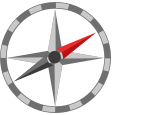**Further exploration**

- You can learn more about matrix operations and other linear algebra topics in the online course [Introduction to Linear Algebra with MATLAB](https://www.mathworks.com/learn/tutorials/introduction-to-linear-algebra-with-matlab.html).

- To learn more about symbolic math, check out the online training course [Introduction to Symbolic Math with MATLAB](https://www.mathworks.com/learn/tutorials/introduction-to-symbolic-math-with-matlab.html).

function [Ai,Bi,ci,vi] = defineMatrices
% This function defines the matrices
    Ai = randi(9,10,10);
    Bi = randi(9,10,10);
    ci = randi(8)+1;
    vi = randi(9,10,1);
end

function validateMatrices
% This function validates that the matrices have been defined
    try
        Ai = evalin("base","Ai");
    catch ME
        warning("Matrices were not defined. They will be auto-populated.")
        evalin("base","[Ai,Bi,ci,vi] = defineMatrices();");
    end
end

function correct = isEqualCheck(userSubmission,correctAnswer)
% This function checks if two results are equal and displays feedback
    correct = true;
    if( isequal(userSubmission,correctAnswer) )
        disp("Correct!")
    else
        warning("Your answer does not match the expected result.")
        correct = false;
    end
end

% Suppress unused suggestions
%#ok<*UNRCH> 
%#ok<*NASGU> 
%#ok<*NBRAK> 